**Load File Audio**

dataset = readtable('dataset.xlsx')

dataset = 50×2 table
                                      Filename                                           Class    
    _____________________________________________________________________________    _____________

    {'C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\l1.wav' }    {'laki-laki'}
    {'C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\l2.wav' }    {'laki-laki'}
    {'C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\l3.wav' }    {'laki-laki'}
    {'C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\l4.wav' }    {'laki-laki'}
    {'C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\l5.wav' }    {'laki-laki'}
    {'C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\l6.wav' }    {'laki-laki'}
    {'C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\l7.wav' }    {'laki-laki'}
    {'C:\Users\acer

audiofile = dataset{:,1};
class = dataset{:,2};


[r,~] = size(audiofile);
data_mfcc = cell(r,1);

**Silence Removal dan Ekstraksi Fitur Mfcc**

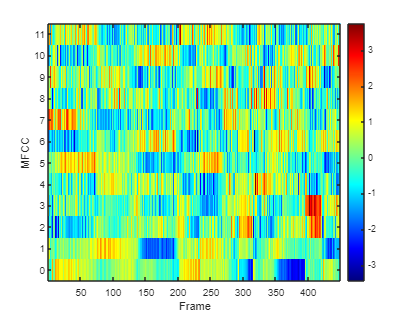


for i = 1:r
    % Membaca Audiofile
    [y, Fs] = audioread(char(audiofile{i}));
    y=y(:,1);

    % Silence removal
    y_speech = baca_dataspeech(y,Fs);

    % Ekstraksi MFCC
    NCoefficients = 12;
    LFrames = 256;
    Overlap = 25;
    fitur_mfcc = ekstraksi_mfcc(y_speech, Fs, NCoefficients, LFrames, Overlap, 1);
    data_mfcc{i} = fitur_mfcc;
end

**Kuantisasi Data**

% Jumlah cluster untuk K-means (jumlah class = jumlah cluster)
N_class = numel(unique(class));

% Penggabungan semua fitur MFCC untuk pengelompokan (clustering)
all_fiturMFCC = vertcat(data_mfcc{:});

% Penerapan K-means untuk kuantisasi fitur MFCC
[idx, C] = kmeans(all_fiturMFCC, N_class);

% Pelabelan tiap frame ke sesuai keterdekatan dengan hasil clustering K-means
kuantisasi_dataMfcc = cell(r,1);
startID = 1;
for i = 1:r
    N_Frames = size(data_mfcc{i}, 1);
    kuantisasi_dataMfcc{i} = idx(startID:startID + N_Frames - 1);
    startID = startID + N_Frames;
end

**Training Data**

% Inisiasi parameter HMM
N_States = N_class^2; % Contoh jumlah state adalah hasul perpangkatan jumlah kelas

% Inisiasi random matriks transisi dan emisi
transisi = rand(N_States); % Random probabilitas transisi
transisi = transisi ./ sum(transisi, 2); % Normalisasi
emisi = rand(N_States, N_class); % Random probabilitas emisi
emisi = emisi ./ sum(emisi,2); % Normalisasi

% Training setiap set data kuantisasi fitur MFCC dengan HMM
model = cell(r,1);
for i = 1:r
    seq = kuantisasi_dataMfcc{i};
    [trans, emis] = hmmtrain(seq', transisi, emisi);
    model{i} = struct('transitions', trans, 'emissions', emis, 'class', class{i});
end

% Simpan haisl training model HMM
save('C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\Model_hmm.mat', 'model');

**Testing Data**

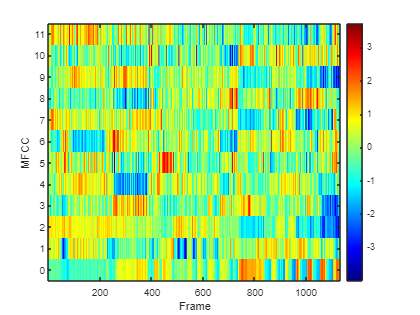

filename = 'testp.wav';
[y, Fs] = audioread(filename);

% Removal silence
y=y(:,1);
y_speech = baca_dataspeech(y, Fs);

% Ekstraksi fitur MFCC
fitur_mfcc_test = ekstraksi_mfcc(y_speech, Fs, NCoefficients, LFrames, Overlap, 1);

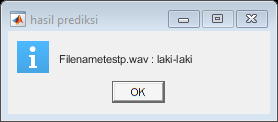

mfccTestData = cell(1,1);
mfccTestData{1} = fitur_mfcc_test;

% Kuantisasi fitur test MFCC dengan pusat cluster hasil training
mfccTestQuantized = cell(1,1);
testFeatures = mfccTestData{1};
numFrames = size(testFeatures, 1);
testQuantized = zeros(numFrames, 1);
for j = 1:numFrames
    distance = sum((C - testFeatures(j, :)).^2,2);
    [~, closestCluster] = min(distance);
    testQuantized(j) = closestCluster;
end
mfccTestQuantized{1} = testQuantized;

% Load model hasil training
load('C:\Users\acera\OneDrive\Documents\MATLAB\klasifikasiSuara\dataset\Model_hmm.mat');

% Inisialisasi storage hasil testing
testResult = cell(1,1);

% Prediksi data test file audio
seq = mfccTestQuantized{1};
logLikelihoods = zeros(r,1);

for j = 1:r
    model_hmm = model{j};
    % Decode sequence dengan model hmm
    [~, logPseq] = hmmdecode(seq', model_hmm.transitions, model_hmm.emissions);
    logLikelihoods(j) = logPseq;
end
logLikelihoods(isnan(logLikelihoods)) = 0; % jika nilai nan diubah menjadi 0

% Pendefinisian model dengan log likehood tertinggi (probabilitas)
[~, bestModelIdx] = max(logLikelihoods);
testResult{1} = model{bestModelIdx}.class;

% Menampilkan hasil prediksi
f = msgbox(['Filename', filename, ' : ' testResult{1}], 'hasil prediksi', 'help');